%gbwslope

# **Influencia do GBW na inclinação da rampa do integrador**

 Considerando o circuito da figura abaixo, que funciona como buffer unitário com a chave aberta e como intevrador quando a chave é fechada, no instante $t_0$, deja-se verificar a influência da GBW do AOP na inclinação da rampa do integrador.

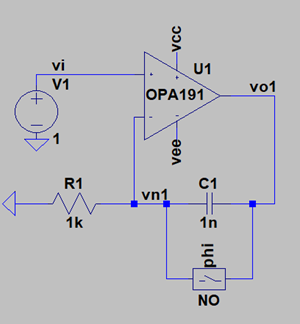

Como forma de analisar o efeito do fechamento da chave em um determinado instante de tempo, assume-se que a resposta do circuito à uma entrada $v_i$ é equivalente à soma das respostas de dois circuitos independentes. O primeiro circuito é um buffer unitário, com sinal de entrada dado por um degrau de $v_i$ para zero, e o segundo, um integrador com sinal de entrada dado por um degrau de zero para $v_i$. 

Considere o modelo de primeira ordem para o AOP dado $v_o =\frac{\omega {\;}_t }{s+\omega_0 }\left(v_p -v_n \right)\;$por em que $\omega {\;}_t$ é o GBW e $\omega_0$ é a frequencia de corte de malha aberta, dada por $\omega_t /A_{\mathrm{OL}}$ sendo $A_{\mathrm{OL}}$ é o ganho de malha aberta. Considere o modelo do integrador dado por $v_n =\frac{s}{s+\omega_c }v_o$, com $\omega_c =\frac{1}{R\ldotp C}$.

Para simulações consideraremos os seguintes parâmetros:

clear;
wt = 2*pi*1e6

wt = 6.2832e+06

Ao = 1e5

Ao = 100000

wo = wt/Ao

wo = 62.8319

wc = 1e6

wc = 1000000

vi = 0.1

vi = 0.1000

### Buffer: Primeiro circuito


$$\begin{array}{l}
v_{\mathrm{o1}} =\frac{\omega {\;}_t }{s+\omega_0 }\left(v_{\mathrm{p1}} -v_{\mathrm{n1}} \right)\\
v_{\mathrm{n1}} =v_{\mathrm{o1}} ,\;\\
\omega_t \gg \omega_o \;\\
\to H_1 \left(s\right)=\frac{v_{\mathrm{o1}} }{v_{\mathrm{p1}} }\approx \frac{\omega {\;}_t }{s+\omega_t }
\end{array}$$


h1 = tf(wt,[1 wt]);
dt = 0.01e-6;
t = 0:dt:10e-6 - dt;
u1 = [vi*ones(length(t)/2,1); zeros(length(t)/2,1)];
vo1 = lsim(h1,u1,t);

### Integrador: segundo circuito


$$\begin{array}{l}
v_{\mathrm{o2}} =\frac{\omega {\;}_t }{s+\omega_0 }\left(v_{\mathrm{p2}} -v_{\mathrm{n2}} \right)\\
v_{\mathrm{n2}} =\frac{s}{s+\omega_c }v_{\mathrm{o2}} ,\;\\
\to H_2 \left(s\right)=\frac{v_{\mathrm{o2}} }{v_{\mathrm{p2}} }=\frac{\omega_t \left(s+\omega_c \right)}{s^2 +\left(\omega_0 +\omega_c +\omega_t \right)s+\omega_0 \omega_c }
\end{array}$$



$$\mathrm{resultando}\;\mathrm{nos}\;\mathrm{polos}\;\mathrm{em}$$



$$\begin{array}{l}
p_{1,2} =\frac{1}{2}\left(\pm \sqrt{{\left(\omega_0 +\omega_c +\omega_t \right)}^2 -4\omega_0 \omega_c }-\left(\omega_0 +\omega_c +\omega_0 \right)\right)\\
\omega_0 \ll \omega_c +\omega_t \;,4\omega_0 \omega_c \ll {\left(\omega_0 +\omega_c +\omega_t \right)}^2 \\
p_{1,2} \approx \frac{1}{2}\left(\pm \left(\omega_c +\omega_t \right)-\left(\omega_c +\omega_t \right)\right)\\
\to p_1 \approx 0,p_2 \approx -\left(\omega_c +\omega_t \right)
\end{array}$$


Assim, a função aproximada pode ser escrita por


$$H_2 \left(s\right)=\frac{v_{\mathrm{o2}} }{v_{\mathrm{p2}} }\approx \frac{\omega_t \left(s+\omega_c \right)}{s\left(s+\omega_c +\omega_t \right)}$$


Essa equação pode ser expandida em fraçoes parciais, $H_2 \left(s\right)\approx A\left(s\right)+B\left(s\right)$, com $A\left(s\right)=\frac{\omega_t \omega_c }{\left(\omega_t +\omega_c \right)s}$ e $B\left(s\right)=\frac{\omega_t^2 /\left(\omega_t +\omega_c \right)}{s+\omega_t +\omega_c }$

O sistema $A\left(s\right)$corresponde a um integrador ideal com ganho de $\frac{\omega_t \omega_c }{\left(\omega_t +\omega_c \right)}$, e $B\left(s\right)$à um sistema de primeira ordem. 

Resposta ao degrau:

ha = tf(wt*wc,[wt+wc 0])


ha =
 
   6.283e12
  ----------
  7.283e06 s
 
Continuous-time transfer function.



hb = tf(wt^2/(wt+wc),[1 wt+wc])


hb =
 
    5.42e06
  ------------
  s + 7.283e06
 
Continuous-time transfer function.



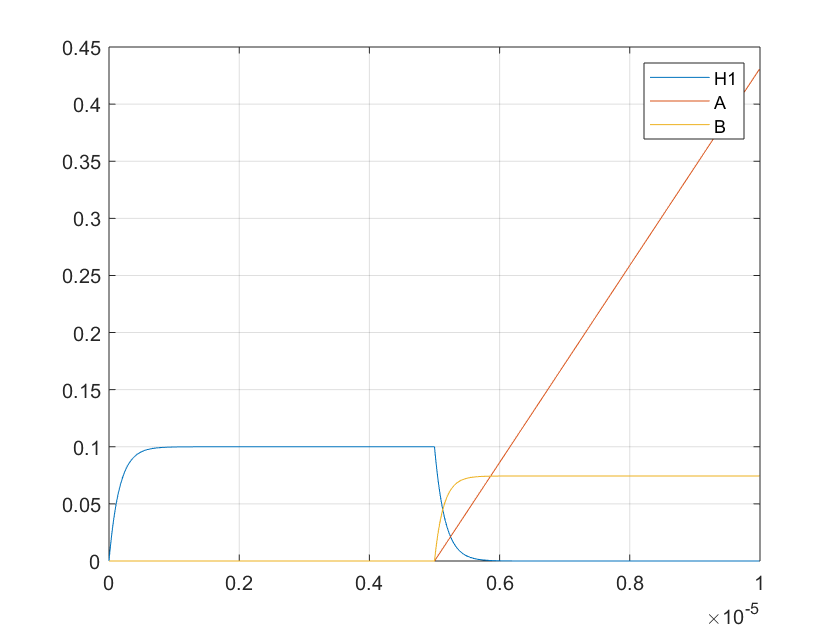

u2 = [zeros(length(t)/2,1); vi*ones(length(t)/2,1)];
voa = lsim(ha,u2,t);
vob = lsim(hb,u2,t);

figure(1);
figure(1);
plot(t,vo1,t,voa,t,vob);grid;
legend('H1','A','B')

Resultado final:

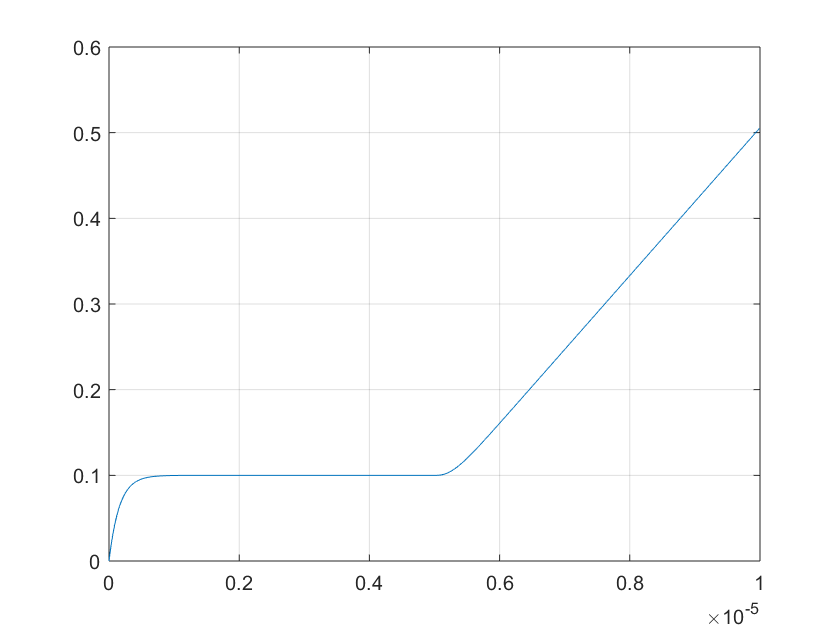

plot(t,vo1+voa+vob);grid

slope=mean(diff(voa(length(voa)/2+10:end)))/dt

slope = 8.6270e+04

Resultado de simulação Spice nivel 1